# 蚁群算法

本文件求解机器人路径规划问题，出自微信公众号：数学建模BOOM，回复“课程”

问题：现有一个区域，其中存在障碍，机器人需要从左上角移动到右下角，求最短路线

求解路径规划，得**先有路径数据：**

1、用栅格表示地图数据，就像日常图片中一个个像素；

2、数据在文件ant.xlsx中，注意要放在与本文件同一文件夹下；

3、读取数据文件ant.xlsx，其中数值为1的元素代表该栅格是路障，0代表可通行。

（代码和文件都在网盘里，公众号：数学建模BOOM，回复“课程”，第一节课有说明）

要进行路径规划，考虑两点：这条路径是否走得通，路径距离多少

因此首要问题：如何表示“走得通”，和“路径距离”，这两点就是算法基本的**路径数据。**

以往的模型算法中，想要矩阵A中第i行、第j列的元素，直接A(i,j)就行；

**本问题中，需经常根据任意****两个****栅格之间是否通行、距离多少做运算**，一开始就算好存在变量里；**算两个栅格间距离的方法（重要）**：给栅格标号，**从左往右、从上往下编号，**第i行第j列的栅格编号为i*ny+nx，这决定了后面代码求数据时的式子。

clc, clear, close all

% 数据在文件ant.xlsx中，注意要放在与本文件同一文件夹下；
% 读取Excel数据的方法在模拟退火一节讲过，用readtable再table2array
% 地形图信息存在25×25的矩阵G里，G中的0代表该位置可通行，1代表有障碍物
G = table2array(readtable('ant.xlsx','Range','A1:Y26'));

[nx,ny] = size(G);     % 像素矩阵G的行数和列数。                  

% tau为什么定义为nx*ny行、nx*ny列的方阵？
% tau(i,j)代表第i*ny+nx个格子的信息素浓度
% 因为所有的运算，都是按"从左往右、从上往下对格子编号"来考虑的（视频和课件里有讲）

tau = 8.*ones(nx*ny,nx*ny);      % 初始信息素浓度矩阵，共nx*ny个格子
k = 100;                         % 迭代次数（指蚂蚁出动多少轮）
m = 80;                          % 蚂蚁个数

alpha = 1;                       % alpha 表征信息素重要程度的参数
beta = 8;                        % beta 表征启发式因子重要程度的参数
rho = 0.4 ;                      % rho 信息素蒸发系数
Q = 1;                           % Q 信息素增加强度系数 

minkl = inf;                     % 记录目前最短路径长度
mink = 0;                        % 记录达到最短路径时的迭代次数
minl = 0;                        % 记录达到最短路径时的蚂蚁编号

D = G2D(G);               % 邻接矩阵，函数定义在文件末尾。求出所有可以行走的格子（相邻或对角相邻）的位置和距离
N = size(D,1);            % N表示问题的规模（象素个数）
a = 1;                    % 小方格象素的边长
Ex = nx;                  % 终止点横坐标
Ey = ny;                  % 终止点纵坐标
S = 1;                              % 最短路径的起始点的栅格序号（默认起始点(1,1)）
E = (Ex-1)*ny + Ey;                % 最短路径的目的点的栅格序号
Eta = zeros(N,1);                   % 启发式信息，取为至目标点的直线距离的倒数

%以下启发式信息矩阵，每个点至目标点的直线距离的倒数
for i = 1:nx 
    for j = 1:ny 
        if i == Ex && j == Ey
            Eta((i-1)*ny+j) = 100; %若为终点则设为一个较大的数，及距离极小。
        else
            Eta((i-1)*ny+j) = 1/((i-Ex)^2+(j-Ey)^2)^0.5; %直线距离
        end
    end 
end

ROUTES = cell(k,m);   % 用cell结构存储每一代的每一只蚂蚁的爬行路线      
PL = zeros(k,m);      % 用矩阵存储每一代的每一只蚂蚁的爬行路线长度

接下来开始启动K轮蚂蚁觅食活动，每轮派出M只蚂蚁

for k = 1:k 
    for m = 1:m 
        % 对当前第k轮迭代、第m只蚂蚁的状态初始化
        W = S;              % 以当前节点作为起始点
        Path = S;           % 初始化爬行路线
        PLkm = 0;           % 初始化爬行路线的长度
        TABUkm = ones(N);   % 禁忌表初始化，记录已经走过的点
        TABUkm(S) = 0;      % 当前已经在初始点了，因此要排除
        DD = D;             % 邻接矩阵初始化

        
        DW = DD(W,:);       % 当前节点的邻接信息，0表示不相邻或有障碍。
        DW1 = find(DW);     % 下一步可以前往的节点，即所有不为0的点
        % 排除已经走过的点
        for j = 1:length(DW1) 
           if TABUkm(DW1(j)) == 0 
              DW(DW1(j)) = 0; 
           end 
        end 

        LJD = find(DW);      %下一步可以前往的节点，即所有不为0的点且没走过的点
        Len_LJD = length(LJD);    % 可选节点的个数
        
        % 蚂蚁未遇到食物，或者陷入死路，或觅食停止
        while W~=E && Len_LJD >= 1 
        %转轮赌法，选择下一步怎么走
            PP = zeros(Len_LJD); 
            for i = 1:Len_LJD 
                PP(i) = (tau(W,LJD(i))^alpha)*((Eta(LJD(i)))^beta);  %每个可走点的权重计算  
            end 
            PP = PP/sum(PP);        % 归一化，建立概率分布
            Pcum = zeros(Len_LJD,1);   
            Pcum(1) = PP(1); 
            for i = 2:Len_LJD 
                Pcum(i) = Pcum(i-1)+PP(i);   %计算累积概率分布
            end 
            Select = find(Pcum >= rand);    %转轮赌法
            to_visit = LJD(Select(1));    %选择下一步怎么走
            
            % 状态更新和记录
            Path = [Path,to_visit];       % 路径增加
            PLkm = PLkm+DD(W,to_visit);   % 路径长度增加
            W = to_visit;                 % 蚂蚁移到下一个节点
            for kk = 1:N 
                if TABUkm(kk) == 0 
                    DD(W,kk) = 0;         %从邻接矩阵中清除已走的点
                    DD(kk,W) = 0; 
                end 
            end 

            TABUkm(W) = 0;    % 记录已访问过的节点，0表示已访问
            DW = DD(W,:);     % 新节点的邻接信息，0表示不相邻或有障碍。
            DW1 = find(DW);   % 下一步可以前往的节点，即所有不为0的点
            % 排除已经走过的点
            for j = 1:length(DW1) 
                if TABUkm(DW1(j)) == 0 
                    DW(j) = 0; 
                end 
            end 

            LJD = find(DW);           % 下一步可以前往的节点，即所有不为0的点且没走过的点
            Len_LJD = length(LJD);    % 可选节点的个数
        end 

        %记下每一代每一只蚂蚁的觅食路线和路线长度      
        ROUTES{k,m} = Path; 
        if Path(end) == E    % 抵达终点
            PL(k,m) = PLkm;  % k代m蚂蚁的路径长度
            if PLkm < minkl 
                mink = k;minl = m;minkl = PLkm;   % 更新最短路径
            end 
        else 
            PL(k,m) = 0; 
        end 
    end 

    %更新信息素
    Delta_Tau=zeros(N,N);       % 更新量初始化
    for m=1:m 
        if PL(k,m)   % 若抵达终点
            ROUT = ROUTES{k,m}; 
            TS = length(ROUT)-1;  % 跳数
            PL_km = PL(k,m);      % k代m蚂蚁的路径长度
            for s = 1:TS
                x = ROUT(s); 
                y = ROUT(s+1); 
                Delta_Tau(x,y) = Delta_Tau(x,y)+Q/PL_km;  % 在路径中留下信息素
                Delta_Tau(y,x) = Delta_Tau(y,x)+Q/PL_km; 
            end 
        end 
    end 
    % 信息素挥发一部分，新增加一部分
    tau = (1-rho).*tau+Delta_Tau;
end 

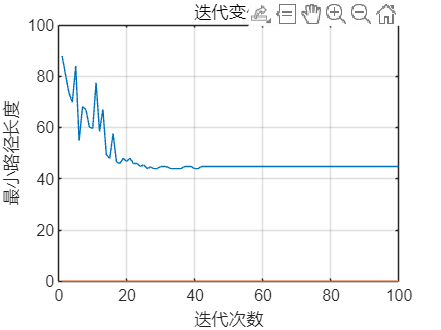

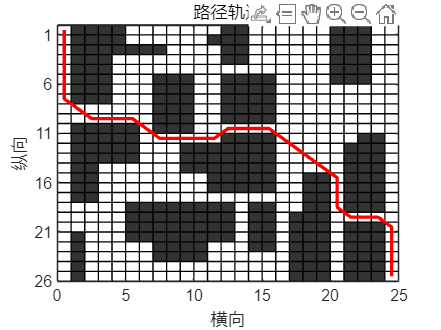

% 绘图
plotif = 1;       % 是否绘图的控制参数
if plotif == 1    % 绘收敛曲线
    minPL = zeros(k); 
    for i = 1:k 
        PLK = PL(i,:); 
        Nonzero = find(PLK); 
        PLKPLK = PLK(Nonzero); 
        minPL(i) = min(PLKPLK); 
    end 

    figure(1) 
    plot(minPL); 

    hold on 
    grid on 

    title('迭代变化'); 
    xlabel('迭代次数'); 
    ylabel('最小路径长度');    
    
    figure(2) % 绘路线图
    for i = 1:nx 
        for j = 1:ny 
            if G(i,j) == 1 
                x1 =j-1;y1 = nx-i; 
                x2 = j;y2 = nx-i; 
                x3 = j;y3 = nx-i+1; 
                x4 = j-1;y4 = nx-i+1; 
                fill([x1,x2,x3,x4],[y1,y2,y3,y4],[0.2,0.2,0.2]); 
                hold on 
            else 
                x1 = j-1;y1 = nx-i; 
                x2 = j;y2 = nx-i; 
                x3 = j;y3 = nx-i+1; 
                x4 = j-1;y4 = nx-i+1; 
                fill([x1,x2,x3,x4],[y1,y2,y3,y4],[1,1,1]); 
                hold on 
            end 
        end 
    end 

    hold on 
    title('路径轨迹'); 
    xlabel('横向'); 
    ylabel('纵向');
    xlim([0,ny]);
    ylim([0,nx]);
    yticklabels(nx:-5:0)
    %set(gca,'xaxislocation','top');
    ROUT = ROUTES{mink,minl}; 
    LENROUT = length(ROUT); 
    Rx = ROUT; 
    Ry = ROUT; 
    for ii = 1:LENROUT 
        Rx(ii) = a*(mod(ROUT(ii),ny)-0.5); 
        if Rx(ii) == -0.5  
            Rx(ii) = ny-0.5; 
        end 
        Ry(ii) = a*(nx-ceil(ROUT(ii)/ny)+0.5); 
    end 
    plot(Rx,Ry,'r','linewidth',2) 
    % fontsize(16,"points")       % 图中字体全都增大到16磅，在输出窗口的图中点击右上角箭头图标，可弹出图片窗口

end 

1、每个栅格是最小行动单元；

2、最小行进路线是相邻两个格子（上下左右）和对角线（左上左下右上右下）

要做的是，求出所有格子两两之间的可行路径位置和距离，其中需要先判断格子是否是障碍，是障碍就直接跳过（走不通）

定义函数G2D，输入参数G（栅格矩阵，元素0代表可走，1代表障碍），得到输出D（最小行进路线对应的格子、距离）

一定要清楚每个变量的意义、每行代码在做什么（课程视频有详细讲解，未查看课程的见文件末尾）

function D=G2D(G)       % G2D函数求出所有可以行走的格子（相邻或对角相邻）的位置和距离
[x,y]=size(G);        

% 根据栅格矩阵G，两两栅格之间的路径；为0代表此路不通，非0值则为距离
D=zeros(x*y,x*y);       

% 看似嵌套多，实际逻辑简单：
% 双重for循环：所有格子两两之间判断是否相邻

% for循环里面的if：判断该格子是否是障碍
% if判断不是障碍、且相邻或对角线相邻，则求距离

% 把符合条件的两个格子记录在矩阵D中：下标代表序号，数值代表距离
% D为什么这样赋值？与所采用的记录方案有关：格子从左往右、从上往下编号；

% i和j的for循环是选择出第i行j列的一个格子，不断迭代，对每一个格子进行
for i=1:x 
    for j=1:y 
        if G(i,j)==0        % 如果该格子不是障碍
            for m=1:x       % m和n的for循环是再找个第m行n列的一个格子
                for n=1:y 
                    if G(m,n)==0    % 如果该格子不是障碍
                        im=abs(i-m);jn=abs(j-n);        % 两个格子之间横向和纵向差值（即两个方向上的坐标距离）
                        if im+jn==1||(im==1&&jn==1)     % 等于1意味着相邻，或横向相乘1且纵向相差1意味着对角线相邻
                            D((i-1)*y+j,(m-1)*y+n)=(im+jn)^0.5;     % 两种相邻情况就求距离
                        end 
                    end 
                end 
            end 
        end 
    end 
end 
end


本文件出自“从零开始学数学建模”课程，

关注微信公众号：数学建模BOOM，回复“课程”。